clear
%load scan_all, R, and t
jj=200;

number_of_scan = 7700;% 7550;
scan_3D=cell(1,number_of_scan);


% 3D scans
n_layer = 4; % without the horizontal
for i = 1:number_of_scan
%     scan_3D{i} = [scan_all{i}(:,2) -scan_all{i}(:,4) -scan_all{i}(:,3)];
    scan_3D{i} = [scan_all{i}(1:512*n_layer,2) -scan_all{i}(1:512*n_layer,4) -scan_all{i}(1:512*n_layer,3)];
end

for i = 1:36%size(R,2)
    R_3D{i} = [R{i};0 0];
    R_3D{i}(:,3) = [0;0;1];    
end
scan_id = 350:jj:number_of_scan;
scan_3D_matched = cell(1,size(R,2));
scan_3D_matched{1} = scan_3D{scan_id(1)}'; % same as map_r


% match scans with the initial scan 1
for count = 1:36%size(R,2)-1
    
    scan_3D_matched{count+1} = R_3D{count} * scan_3D{scan_id(count+1)}'  + [t{count};0];
    
    if count>1
        prev_count = count-1;
        for ii = 1:count-1
            scan_3D_matched{count+1} = R_3D{prev_count} * scan_3D_matched{count+1}  + [t{prev_count};0];
            prev_count = prev_count-1;
        end
    end
end

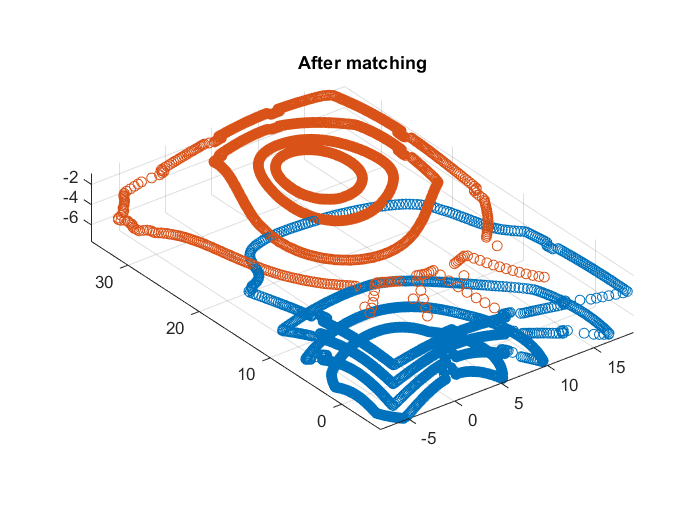

scan_plot = 20;
scatter3(scan_3D_matched{1}(1,:),scan_3D_matched{1}(2,:),scan_3D_matched{1}(3,:))
axis equal
hold  on
scatter3(scan_3D_matched{scan_plot}(1,:),scan_3D_matched{scan_plot}(2,:),scan_3D_matched{scan_plot}(3,:))
title('After matching')
hold off

% make all the points form the matched scans to one matrix

for i = 1 : 37%size(scan_3D_matched,2)
    a = (i-1) * 512*n_layer+1;
    b = 512*n_layer*i;
    x(a:b) = scan_3D_matched{i}(1,:);
    y(a:b) = scan_3D_matched{i}(2,:);
    z(a:b) = scan_3D_matched{i}(3,:);
end

z = z + 6.9; % desired altitude y


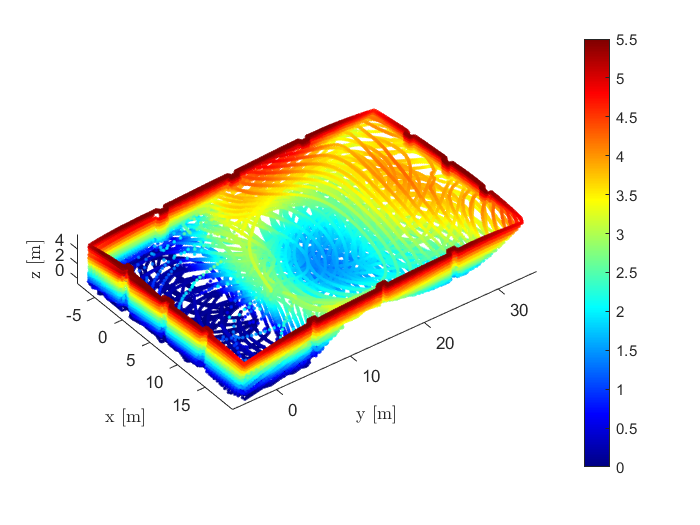

figure;
scatter3(x,y,z,[],z,'.')
%pcshow(p_Cloud_glob);
xlabel('x [m]','Interpreter','latex')
ylabel('y [m]','Interpreter','latex')
zlabel('z [m]','Interpreter','latex')
axis equal
% xlim([-1 41])
% ylim([-1 31])
% zlim([0 7.5])

caxis([0 5.5])
% set(gca,'fontsize', 18)
set(gca,'fontsize', 10)
view([-45 75])

grid off
colormap(jet)

colorbar



view([53.27 37.34])

% % Make initial pose to actual 
% theta = pi-0.0323;
% RR = [cos(theta) -sin(theta); sin(theta) cos(theta)];
% 
% xy = RR * [robot_pose_x;robot_pose_y];
% xy = xy + [xx(1); yy(1)];

% meshgrid the top view
p.xv = linspace(min(x),max(x), (max(x)-min(x))*50);
p.yv = linspace(min(y),max(y), (max(y)-min(y))*50);
[X,Y] = meshgrid(p.xv, p.yv);

Z = griddata(x,y,z,X,Y,'linear'); %natural %linear


% The smoothing (with sgolayfilt(Z,order,length of the moving windows))
t1 = sgolayfilt(Z.',2,25*1); %smoothing over the x-axis
t2 = sgolayfilt(Z,2,25*1); %smoothing over the y-axis
Z_f  = (t1.'+t2)/2; %smoothing in booth directions

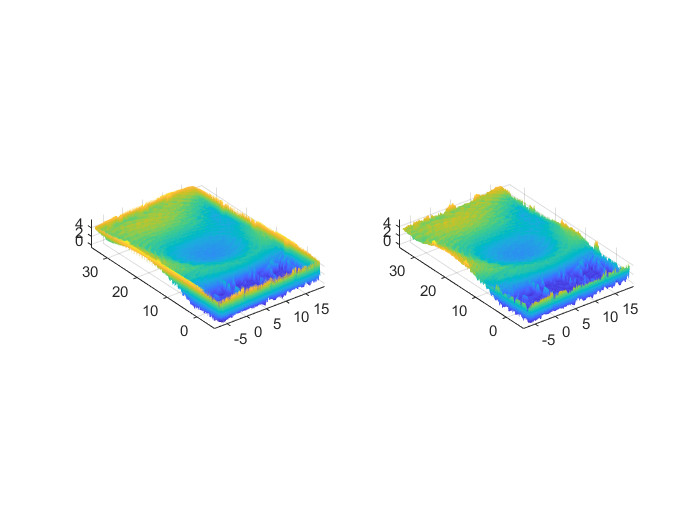

figure
subplot(121)
surf(X,Y,Z)
shading interp, axis equal
subplot(122)
surf(X,Y,Z_f)
shading interp, axis equal


% surf(p.X, p.Y, p.Z,'FaceColor','flat','FaceAlpha',1)
% xlabel('x [m]')
% ylabel('y [m]')
% zlabel('z [m]')
% grid off
% %set(gca, 'ZLim',[-10 500])
% shading interp
% axis tight
% axis equal
% colormap(jet)
% % xlim([-1 41])
% % ylim([-1 31])
% % zlim([0 7.5])
% 
% caxis([0 5.5])
% %view([135 30])
% set(gca,'fontsize', 18)
% view([-45 75])
% colorbar


% Volume 
zi=Z_f;
zi(zi<0)=0;
dx = (max(p.xv)-min(p.xv))/length(p.xv);
dy = (max(p.yv)-min(p.yv))/length(p.yv);
vol1 = dx*dy*sum(zi(:));
vol2 = dx*dy*sum(zi(~isnan(zi)))

vol2 = 2.1834e+03


% Volume = 2117.50 cubic millimeters
Error_v_f = ((vol2-2117.5)/2117.5)*100

Error_v_f = 3.1142


% Volume 
zi=Z;
zi(zi<0)=0;
dx = (max(p.xv)-min(p.xv))/length(p.xv);
dy = (max(p.yv)-min(p.yv))/length(p.yv);
vol1 = dx*dy*sum(zi(:));
vol2 = dx*dy*sum(zi(~isnan(zi)))

vol2 = 2.2965e+03


% Volume = 2117.50 cubic millimeters
Error_v_f = ((vol2-2117.5)/2117.5)*100

Error_v_f = 8.4516